## H2

#### Apartat 1

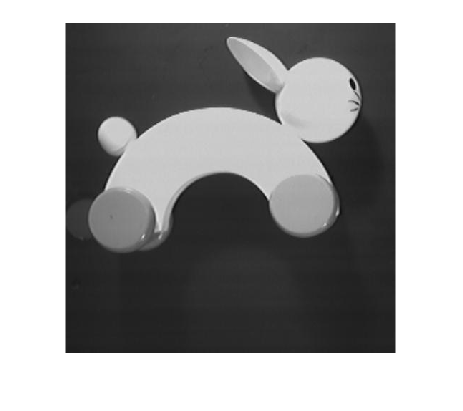

I = imread('rabbit.jpg');
imshow(I)

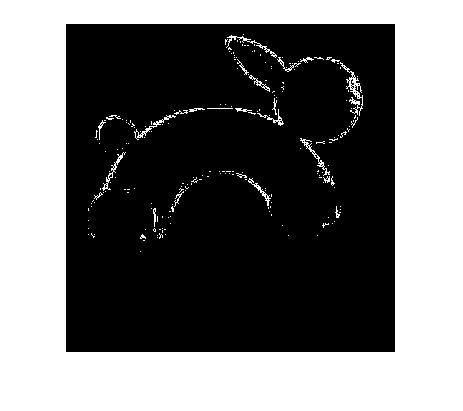

hL = [0 1 0; 1 -4 1; 0 1 0];
L = abs(imfilter(double(I), hL));
L = L > 20;
imshow(L,[])

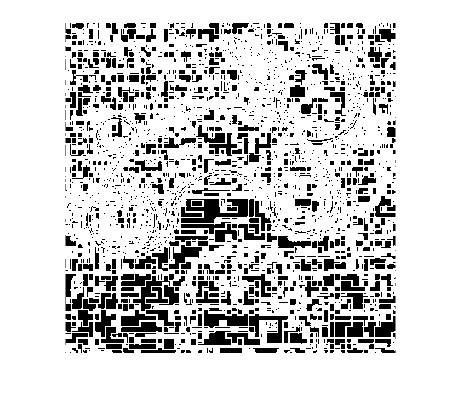



L2 = imfilter(double(I), hL);
P = L2 > 0; % pixels amb valor positiu
N = L2 < 0; % pixels amb valor negatiu

SP = colfilt(P,[3 3],"sliding",@sum); % fa la suma dels veis positius
SN = colfilt(N,[3 3],"sliding",@sum); % fa la suma dels veis negatius

UP = SP > 0; % almenys un vei positiu
UN = SN > 0; % almenys un vei negatiu

Z = UP & UN;
imshow(Z);

#### Apartat 2

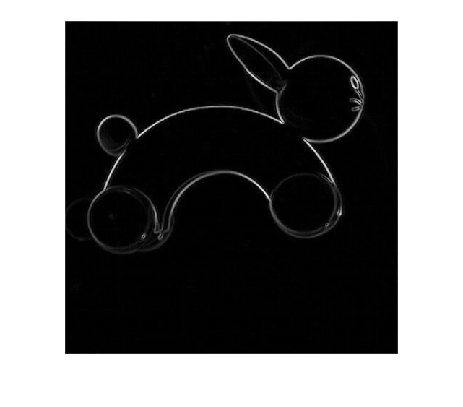

hx = [1 0 -1; 2 0 -2; 1 0 -1];
hy = hx';
Gx = abs(imfilter(double(I), hx));
Gx = Gx/max(max(Gx));
Gy = abs(imfilter(double(I), hy));
Gy = Gy/max(max(Gy));
G = (Gx + Gy);
imshow(G,[])

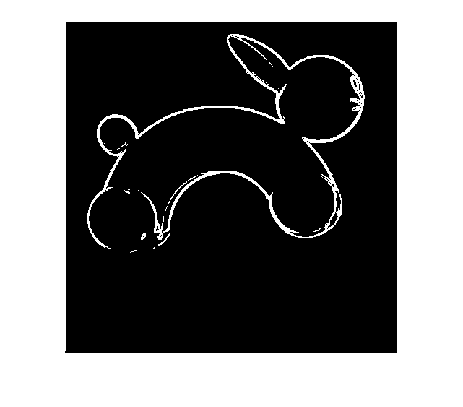

G2 = G > 0.2;
imshow(G2,[])